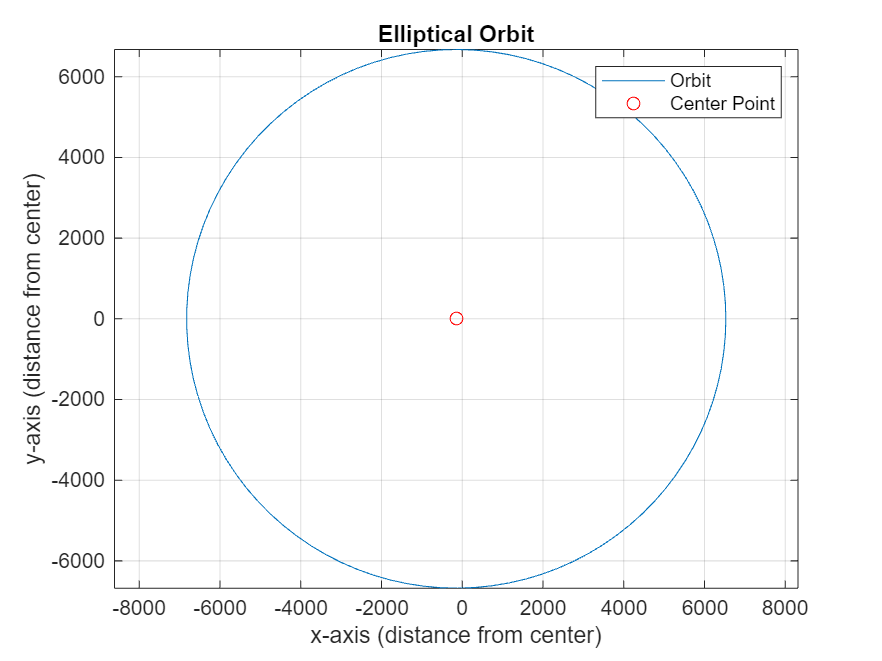

clear;
clf;
close all;

duE = 6378.136; % conversion from du earth to km
tuE = 806.8118744; % converson from tu earth to seconds
muE = 3.986004418*10^5; % mu for earth




b = sqrt(a^2 * (1 - e^2));   % Semi-minor axis
c = e * a; % focus distance

% Define the parameter t
t = linspace(0, 2*pi);

% Parametric form of an ellipse for an orbit
theta = atan2(b.*sin(t), a.*cos(t));
r = (a * (1 - e^2)) ./ (1 + e.*cos(theta));
x = r .* cos(theta);
y = r .* sin(theta);

% Plotting
plot(x, y)
hold on
plot(-c, 0, 'r.') % Mark the center point
axis equal
title('Elliptical Orbit')
xlabel('x-axis (distance from center)')
ylabel('y-axis (distance from center)')
legend('Orbit', 'focus point')
grid on

orbitalPeriod = @(a,mu) 2*a^(3/2)*pi*mu^(-1/2); %finds orbital period from mu and the semimajor axis a

orbitalVelocity = @(r,a,mu) sqrt( (2*mu/r)-(mu/a)); % finds orbital period from the position r the semi major axis a and mu

orbitalEnergy = @(a,mu) -mu/(a*2); % finds orbital energy from mu and the semimajor axis a


v1 = orbitalVelocity((200+duE),(200+duE),muE)

v1 = 7.7843

E1 = orbitalEnergy((200+duE),muE)

E1 = -30.2974

rGEO = 35786+duE

rGEO = 4.2164e+04

v2 = orbitalVelocity((200+duE),(0.5*(200+duE+rGEO)),muE)

v2 = 10.2388

v3 = orbitalVelocity(rGEO,(0.5*(200+duE+rGEO)),muE)

v3 = 1.5974

v4 = sqrt(muE/rGEO)

v4 = 3.0747

v12 = v2 - v1

v12 = 2.4546

v34 = sqrt(v3^2+v4^2-2*v3*v4*cosd(28.5))

v34 = 1.8365

vtotal = v12 + v34

vtotal = 4.2911